close all; clear; clc;

# P80 characterization tests 4 bat STv4 and STv4.1

(ramp up and down in steps  **- Both tests**)

**file name**: STv4_P8027d_20181115.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 27/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data - cont. recording

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_P8027d_20181115.mat');
time = STv4_P8027d_20181115(:,1);                       % [sec]
PWM = STv4_P8027d_20181115(:,2);                        % [micro sec]
Q = STv4_P8027d_20181115(:,4);                          % [ft.lbf]
T = STv4_P8027d_20181115(:,5);                          % [lbf]
Input_V = STv4_P8027d_20181115(:,6);                    % [Volts]
Input_A = STv4_P8027d_20181115(:,7);                    % [Amps]
rot_speed_rpm = STv4_P8027d_20181115(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad = rot_speed_rpm .* (pi/30);   % [rad/sec]
P_in_W = STv4_P8027d_20181115(:,9);                     % [Watts]
P_out_W = STv4_P8027d_20181115(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = STv4_P8027d_20181115(:,11);                 % [%]
Prop_Eff = STv4_P8027d_20181115(:,12);                  % [lbf/Watts]
Overall_Eff = STv4_P8027d_20181115(:,13);               % [lbf/Watts]  
ESC_Temp = STv4_P8027d_20181115(:,14);                  % [F]
Motor_Temp = STv4_P8027d_20181115(:,15);                % [F]

disk_loading = T ./ area;                     % [lb/sq.ft]

Settling_time = STv4_P8027d_20181115(:,17); % [s]
Max_Acc = STv4_P8027d_20181115(:,18);      % [RPM]

%Thrust, Power, and Torque Coefficents
C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);






## Measured Data - one point per step

This format assumes that the data output from RC Benchmark has not been changed

load('STv4_1_P8027d_20181115.mat');
time1 = STv4_1_P8027d_20181115(:,1);                       % [sec]
PWM1 = STv4_1_P8027d_20181115(:,2);                        % [micro sec]
Q1 = STv4_1_P8027d_20181115(:,4);                          % [ft.lbf]
T1 = STv4_1_P8027d_20181115(:,5);                          % [lbf]
Input_V1 = STv4_1_P8027d_20181115(:,6);                    % [Volts]
Input_A1 = STv4_1_P8027d_20181115(:,7);                    % [Amps]
rot_speed_rpm1 = STv4_1_P8027d_20181115(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1 = rot_speed_rpm1 .* (pi/30);   % [rad/sec]
P_in_W1 = STv4_1_P8027d_20181115(:,9);                     % [Watts]
P_out_W1 = STv4_1_P8027d_20181115(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                  % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff1 = STv4_1_P8027d_20181115(:,11);                 % [%]
Prop_Eff1 = STv4_1_P8027d_20181115(:,12);                  % [lbf/Watts]
Overall_Eff1 = STv4_1_P8027d_20181115(:,13);               % [lbf/Watts]  
ESC_Temp1 = STv4_1_P8027d_20181115(:,14);                  % [F]
Motor_Temp1 = STv4_1_P8027d_20181115(:,15);                % [F]

disk_loading1 = T1 ./ area;                     % [lb/sq.ft]

Settling_time1 = STv4_1_P8027d_20181115(:,17); % [s]
Max_Acc1 = STv4_1_P8027d_20181115(:,18);      % [RPM]

%Thrust, Power, and Torque Coefficents
C_T1 = T1 ./ (p .* area * (rot_speed_rad1 * radius).^2);
C_P1 = P_out1 ./ (p .* area .* (rot_speed_rad1 .* radius).^3);
C_Q1 = Q1 ./ (p .* area .* (rot_speed_rad1 .* radius).^(2) .* radius);

throttle = (PWM -1000) ./10;
throttle1 = (PWM1 - 1000) ./ 10;

## Plots

The following are standard charts. Remove, add, and edit as needed.

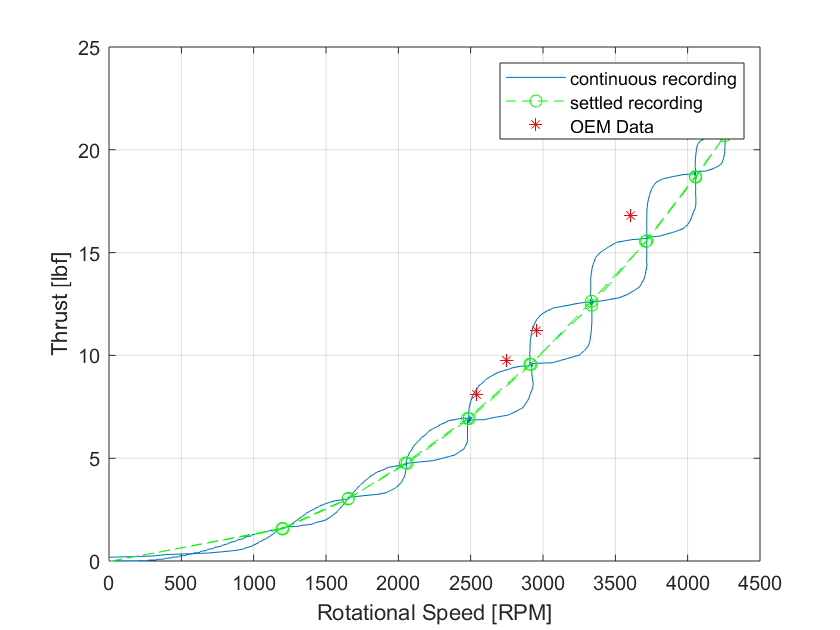

figure(1)
plot(rot_speed_rpm, T, rot_speed_rpm1, T1, 'go--',...
    2541, 8.12, 'r*', 2750, 9.73, 'r*', 2955, 11.23, 'r*', 3172, 12.84, ...
    3602, 16.79, 'r*', 3998, 20.79, 'r*', 4563, 27.43, 'r*'); 
%title('P80 full power Thrust Curve with OEM Data (48 volts)'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');
legend('continuous recording', 'settled recording', 'OEM Data');
ylim([0 25])

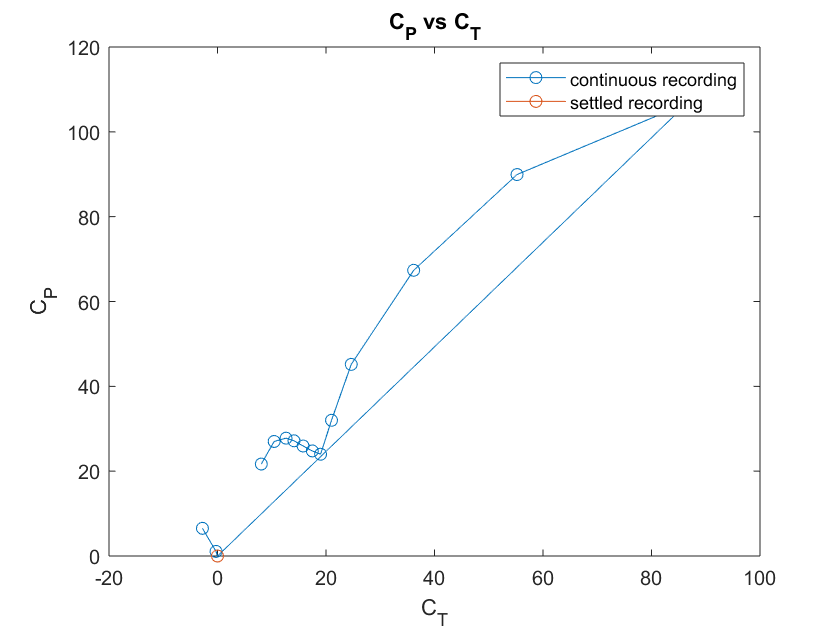


figure(2)
plot(C_T, C_P,'o-', C_T1, C_P1, 'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')
legend('continuous recording', 'settled recording')

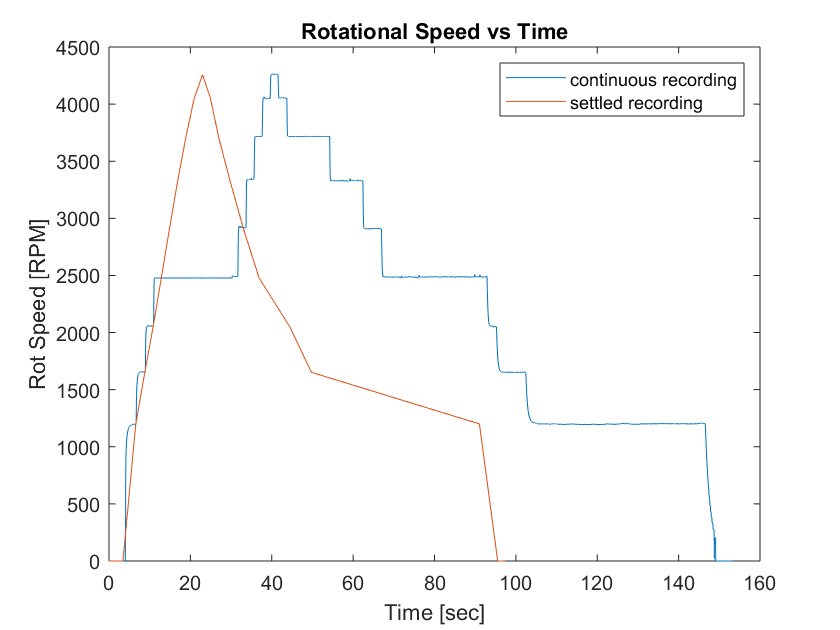


figure(3)
plot(time, rot_speed_rpm, time1, rot_speed_rpm1); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')
legend('continuous recording', 'settled recording');

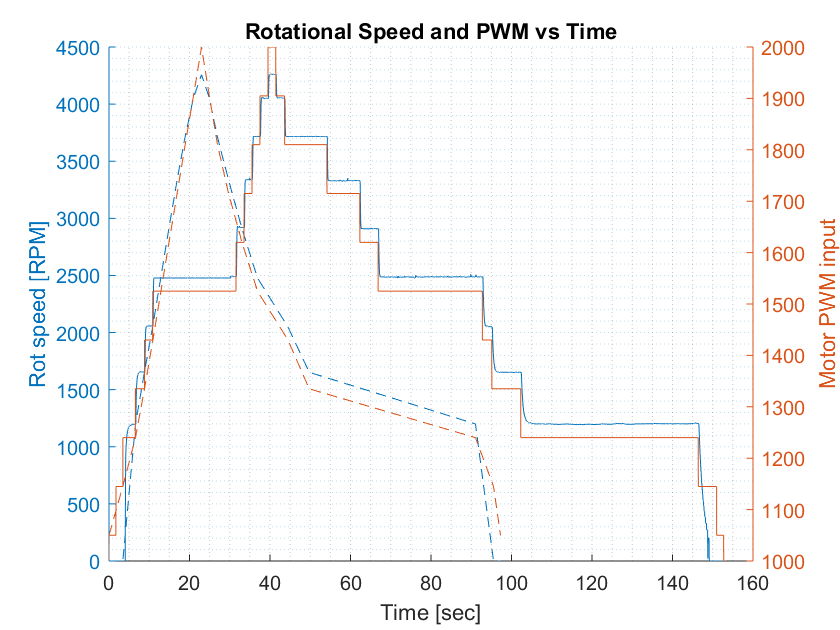


figure(4)
hold on
yyaxis left
plot(time, rot_speed_rpm, time1, rot_speed_rpm1);
ylabel('Rot speed [RPM]');
yyaxis right
plot(time, PWM, time1, PWM1);
ylabel('Motor PWM input');
title('Rotational Speed and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

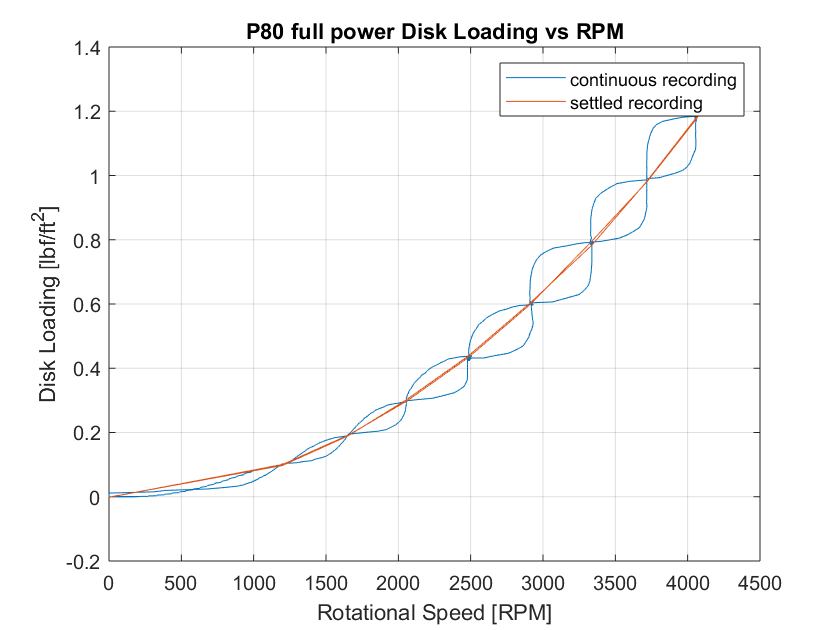

%legend('continuous recording', 'recorded after settled');

figure(5)
plot(rot_speed_rpm, disk_loading, rot_speed_rpm1, disk_loading1); title('P80 full power Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on'); legend('continuous recording', 'settled recording');

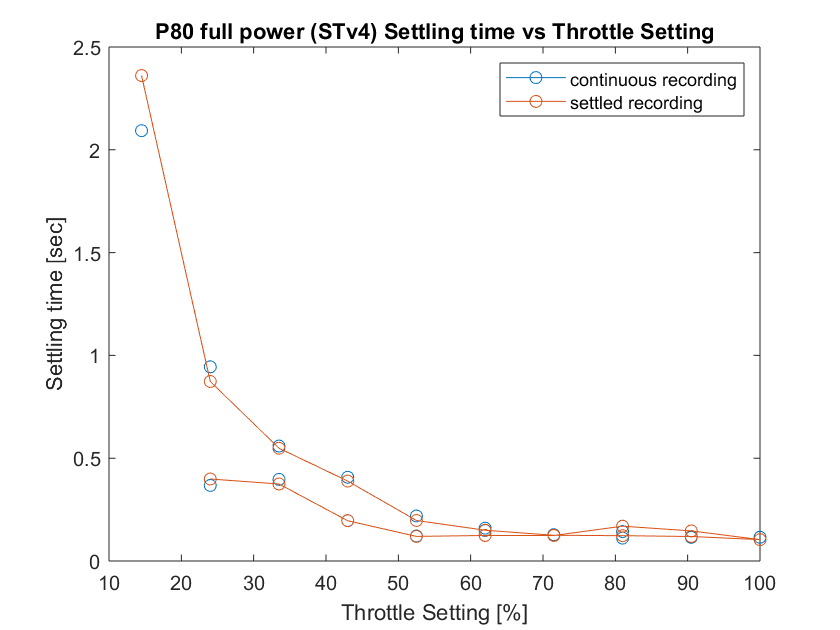


figure(6)
plot(throttle, Settling_time, 'o-', throttle1, Settling_time1, 'o-');
legend('continuous recording','settled recording'); title('P80 full power (STv4) Settling time vs Throttle Setting');
xlabel('Throttle Setting [%]'); ylabel('Settling time [sec]');

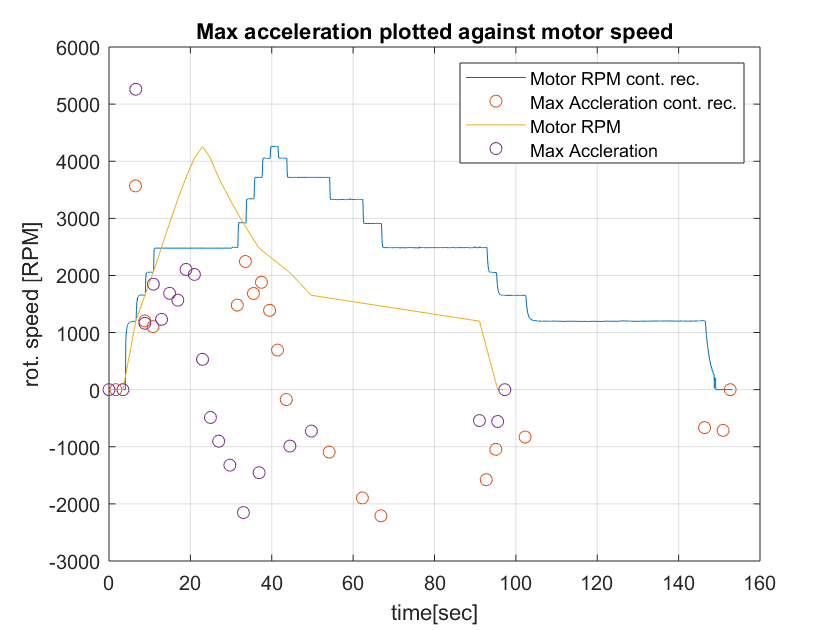


figure(7)
plot(time, rot_speed_rpm, time, Max_Acc, 'o', time1, rot_speed_rpm1, time1, Max_Acc1, 'o');
title('Max acceleration plotted against motor speed')
xlabel('time[sec]'); ylabel('rot. speed [RPM]'); 
legend('Motor RPM cont. rec.', 'Max Accleration cont. rec.', 'Motor RPM', 'Max Accleration'); 
grid('on');

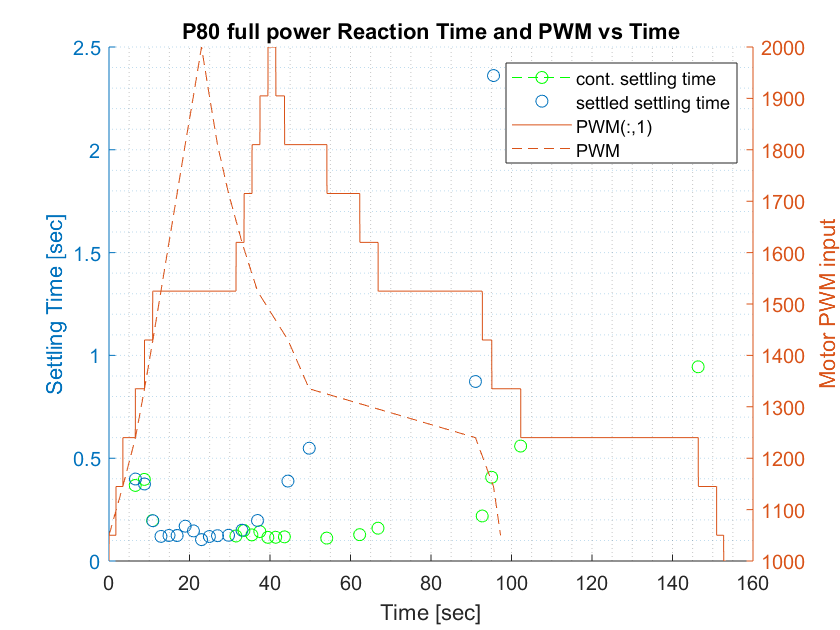


figure(8)
hold on
yyaxis left
plot(time, Settling_time, 'g--o', time1, Settling_time1, 'o');
ylabel('Settling Time [sec]');
legend('cont. settling time', 'settled settling time');
yyaxis right
plot(time, PWM, time1, PWM1, 'DisplayName', 'PWM' );
ylabel('Motor PWM input');
title('P80 full power Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

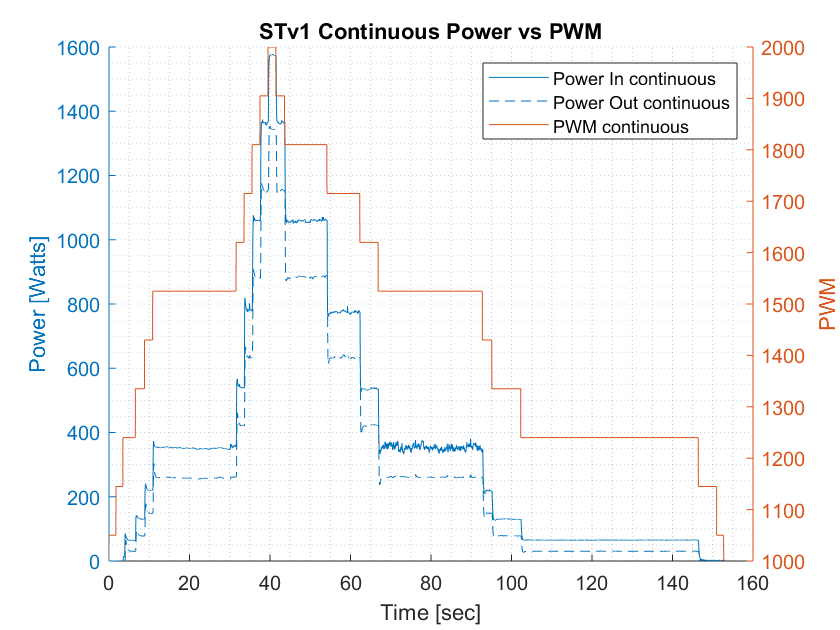


figure(9)
hold on
yyaxis left
plot(time, P_in_W, time, P_out_W);
ylabel('Power [Watts]');
legend('Power In continuous', 'Power Out continuous');
yyaxis right
plot(time, PWM, 'DisplayName','PWM continuous');
ylabel('PWM');
title('STv1 Continuous Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

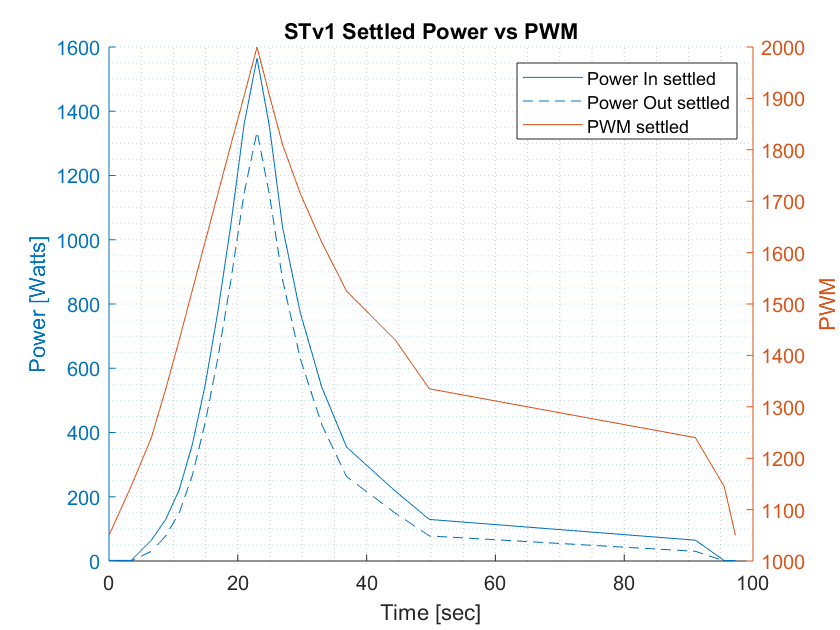


figure(10)
hold on
yyaxis left
plot(time1, P_in_W1, time1, P_out_W1);
ylabel('Power [Watts]');
legend('Power In settled', 'Power Out settled');
yyaxis right
plot(time1, PWM1, 'DisplayName','PWM settled');
ylabel('PWM');
title('STv1 Settled Power vs PWM');
xlabel('Time [sec]');
grid('minor');
hold off

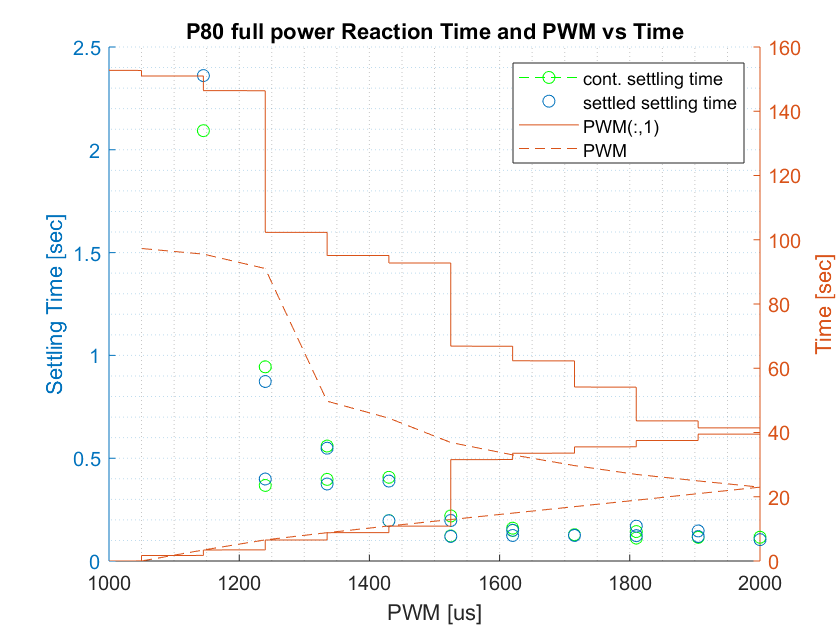


figure(11)
hold on
yyaxis left
plot(PWM, Settling_time, 'g--o', PWM1, Settling_time1, 'o');
ylabel('Settling Time [sec]');
legend('cont. settling time', 'settled settling time');
yyaxis right
plot(PWM, time, PWM1, time1, 'DisplayName', 'PWM' );
ylabel('Time [sec]');
title('P80 full power Reaction Time and PWM vs Time');
xlabel('PWM [us]');
grid('minor');
hold off

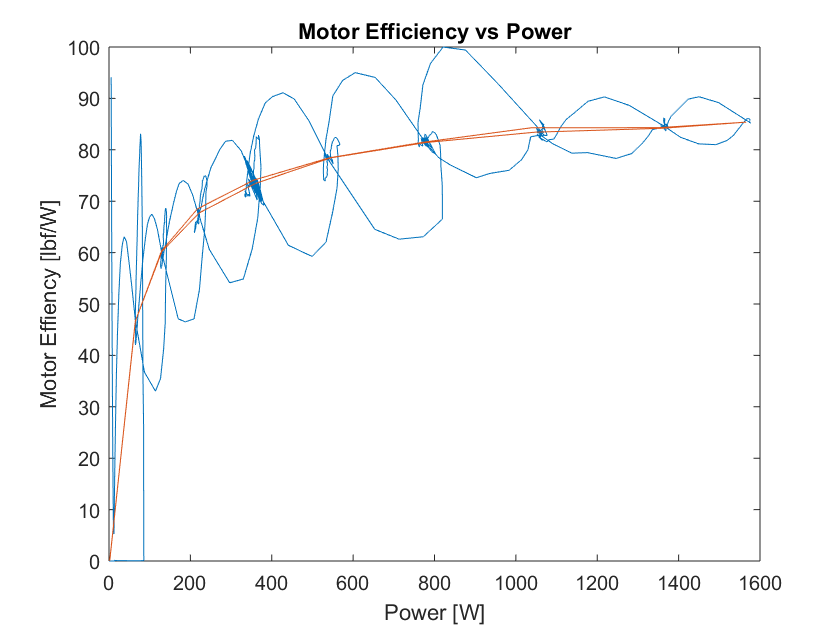


figure(12)
plot(P_in_W(1:6162), Motor_Eff(1:6162), P_in_W1, Motor_Eff1);
xlabel('Power [W]'); ylabel('Motor Effiency [lbf/W]');
title('Motor Efficiency vs Power');

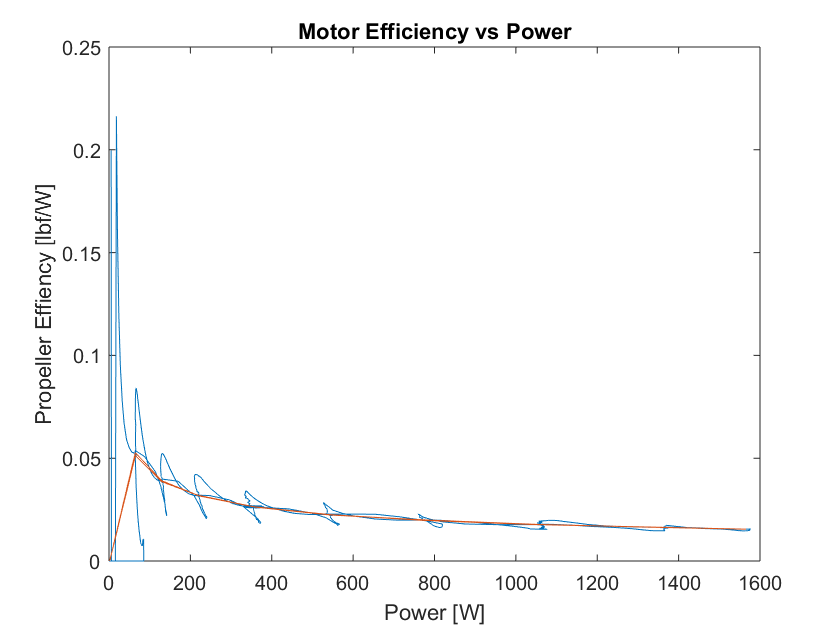


figure(13)
plot(P_in_W(1:6162), Prop_Eff(1:6162), P_in_W1, Prop_Eff1);
xlabel('Power [W]'); ylabel('Propeller Effiency [lbf/W]');
title('Motor Efficiency vs Power');

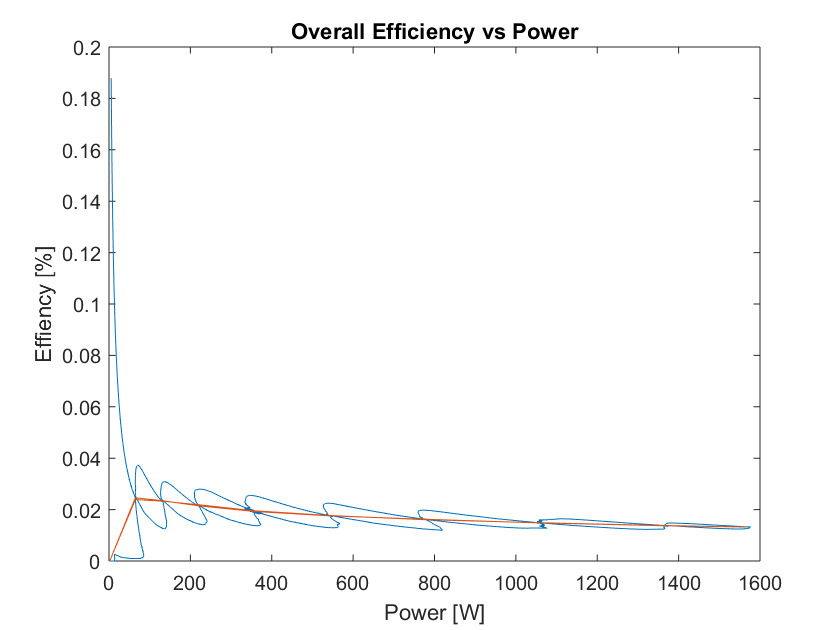


figure(14)
plot(P_in_W(1:6162), Overall_Eff(1:6162), P_in_W1, Overall_Eff1);
xlabel('Power [W]'); ylabel('Effiency [%]');
title('Overall Efficiency vs Power');

## Comparing Data to Momentum Theory

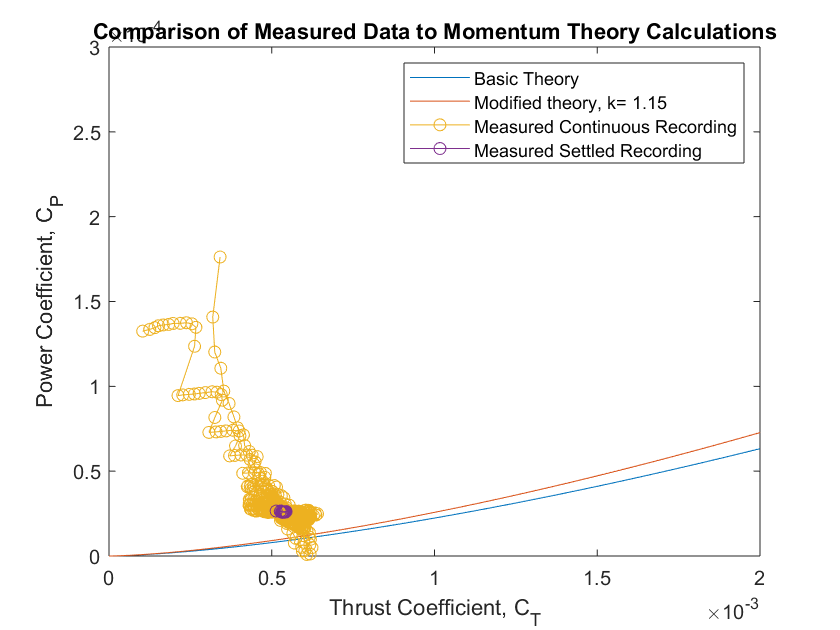

k = 1.15;
C_T_theory = linspace(0, 0.01, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi, C_T(176:6237), C_P(176:6237), 'o-', C_T1, C_P1, 'o-');
title('Comparison of Measured Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.15', 'Measured Continuous Recording','Measured Settled Recording');
ylim([0 0.0003]); xlim([0 0.002]);